## 0. Initialization

**Cleaning the environment**

clear; close all; clc;

**Installation and import**

Download and unzip the content of the folder `'LoopDetect_for_Matlab'`. Within the MATLAB session, navigate to this folder and work there or add the path of the folder to MATLAB's search path for the current MATLAB session by MATLAB's `addpath()` function. Deending on where you stored the folder, its name could be something like `'/Users/Desktop/LoopDetect' `on Mac or `'C:\matlab\LoopDetect'` on Windows.

% Retrieve the LoopDetect folder location when having navigated to the folder
% within the MATLAB session.
LoopDetect_Folder_Name = fullfile(pwd, '..', 'LoopDetect_2025', 'src', 'loopdetect_for_matlab');
LoopDetect_Folder_Name = char(java.io.File(LoopDetect_Folder_Name).getCanonicalPath); % normalize path
addpath(LoopDetect_Folder_Name);

**Models:**

Models = fullfile(pwd, '..', 'LoopDetect_2025', 'src', 'models');
Models = char(java.io.File(Models).getCanonicalPath); % normalize path
addpath(Models);

## 1. Model

This model for complex formation is not yet in the library. The implementation is written here:

function dx = model_complex_formation(t, x, params)
    % model_complex_formation
    % Simple reversible complex formation:
    % A + B <-> AB
    %
    % x(1) = A
    % x(2) = B
    % x(3) = AB
    %
    % params(1) = k1 (association rate)
    % params(2) = k2 (dissociation rate)

    dx = zeros(3,1);

    A  = x(1);
    B  = x(2);
    AB = x(3);

    k1 = params(1);
    k2 = params(2);

    dx(1) = -k1 * A * B + k2 * AB;   % dA/dt
    dx(2) = -k1 * A * B + k2 * AB;   % dB/dt
    dx(3) =  k1 * A * B - k2 * AB;   % dAB/dt
end


Parameters:

params=[1.0, 2.0]

params =      1     2


s_star = [10.0, 5.0, 2.0]' 

s_star =     10
     5
     2


## 2. Result reproduction

### **Loop structure:**

loop_list=find_loops_vset(@(x)model_complex_formation(1,x,params),s_star,10);
disp(loop_list{1})

       loop        length    sign
    ___________    ______    ____

    {[  2 1 2]}      2         1 
    {[3 1 2 3]}      3        -1 
    {[  3 1 3]}      2         1 
    {[3 2 1 3]}      3        -1 
    {[  3 2 3]}      2         1 
    {[    1 1]}      1        -1 
    {[    2 2]}      1        -1 



first_loop=loop_list{1}.loop{1}

first_loop =      2     1     2


disp(loop_summary(loop_list{1}))

                length_1    length_2    length_3
                ________    ________    ________

    total          2           3           2    
    negative       2           0           2    
    positive       0           3           0    



Filter loops:

noi = 2;
loops_with_node2=loop_list{1}(...
    cellfun(@(z) ismember(noi,z),loop_list{1}.loop),:)

loops_with_node2 = 5×3 table
       loop        length    sign
    ___________    ______    ____

    {[  2 1 2]}      2         1 
    {[3 1 2 3]}      3        -1 
    {[3 2 1 3]}      3        -1 
    {[  3 2 3]}      2         1 
    {[    2 2]}      1        -1 


Search a loop list for loops containing specific edges defined by the indices of the ingoing and outgoing nodes. This example returns the indices of all loops with a regulation of node 3 by node 2. These are only two here.

loop_edge_ind=find_edge(loop_list{1},2,3);
loops_with_edge_2_to_3=loop_list{1}(loop_edge_ind,:)

loops_with_edge_2_to_3 = 2×3 table
       loop        length    sign
    ___________    ______    ____

    {[3 1 2 3]}      3        -1 
    {[  3 2 3]}      2         1 


for i=1:2
    disp(loops_with_edge_2_to_3.loop{i})
end

     3     1     2     3

     3     2     3



### **Jacobian matrix:**

The functions `numerical_jacobian()` and `numerical_jacobian_complex()` provide numerical estimates of the Jacobian matrix of an ODE system at a chosen state vector $s_{\ast }$. They implement, respectively, a **finite-difference method using real perturbations** and the **complex-step method**, the latter offering higher accuracy due to the absence of subtractive cancellation errors (see Martins *et al*., 2003) and making use of MATLAB’s built-in support for complex arithmetic.

The function handle **f** (in the example derived from `func_POSm4`, the positive-feedback chain model of Baum *et al*., 2016) must refer to a function that returns the vector of time derivatives,


$$f_i \left(s\right)=\frac{\;{\textrm{dS}}_i }{\textrm{dt}}\ldotp$$


When used with `numerical_jacobian_complex()`, this function is required to depend **only** on the state variables. Any additional dependencies—such as model parameters—must be fixed beforehand so that $f$ effectively maps only the variable vector $s$ to its corresponding derivative vector.

j_matrix=numerical_jacobian_complex(@(x)model_complex_formation(1,x,params),...
s_star);
signed_jacobian=sign(j_matrix)

signed_jacobian =     -1    -1     1
    -1    -1     1
     1     1    -1


Need to verify: Function `find_loops(j_matrix)` will give result with different data structure than `find_loops_vset(@(x)func(...), ...)`.

loop_list_2=find_loops(j_matrix)

loop_list_2 = 8×3 table
       loop        length    sign
    ___________    ______    ____

    {[  2 1 2]}      2         1 
    {[3 1 2 3]}      3        -1 
    {[  3 1 3]}      2         1 
    {[3 2 1 3]}      3        -1 
    {[  3 2 3]}      2         1 
    {[    1 1]}      1        -1 
    {[    2 2]}      1        -1 
    {[    3 3]}      1        -1 


loop_list_2

loop_list_2 = 8×3 table
       loop        length    sign
    ___________    ______    ____

    {[  2 1 2]}      2         1 
    {[3 1 2 3]}      3        -1 
    {[  3 1 3]}      2         1 
    {[3 2 1 3]}      3        -1 
    {[  3 2 3]}      2         1 
    {[    1 1]}      1        -1 
    {[    2 2]}      1        -1 
    {[    3 3]}      1        -1 


loop_list

loop_list = 1×1 cell array
    {7×3 table}


### Temporal dynamics

Solving the ODE model to observe temporal dynamics

tspan = linspace(0, 1, 1001);
t_perb = 0.2 % where pertubation happens

t_perb = 0.2000

opts = odeset('RelTol',1e-6,'AbsTol',1e-9);  % closer to typical SciPy accuracy
[t,sol] = ode15s(@(t,x) model_complex_formation(1,x,params), tspan, s_star, opts);
%s_star=sol(end,:); %the last point of the simulation is chosen

Plot

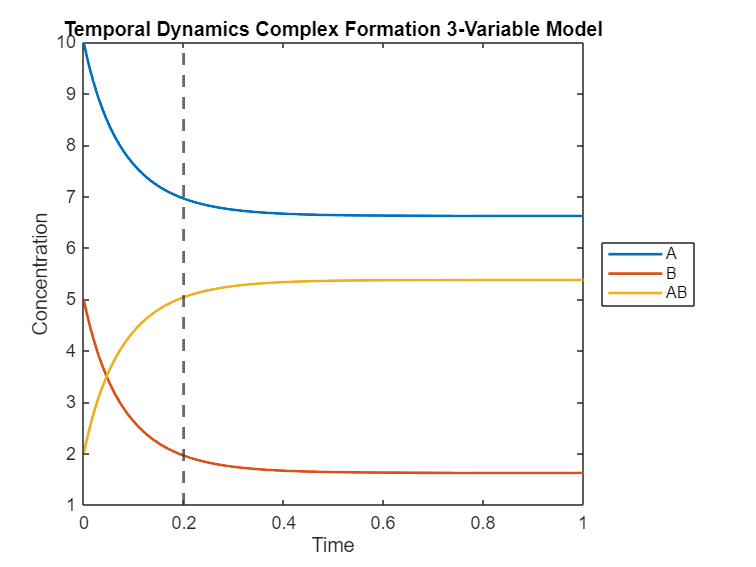

figure;
plot(t, sol, 'LineWidth', 1.5);
xline(t_perb, '--', 'LineWidth', 1.5);
xlabel('Time');
ylabel('Concentration');
xlim([0,1]);
title('Temporal Dynamics Complex Formation 3-Variable Model');
legend('A','B','AB','Location','eastoutside'); % southeast

### Pertubation Analysis

colors = [
    0.85 0.33 0.10;   % orange (A)
    0.00 0.45 0.74;   % blue   (B)
    0.30 0.75 0.93    % light blue (AB)
];

When A is perturbed:

dt = 0.001;
tspan = (0:dt:1)';            % matches Python delta_t
t_perb = 0.2;

opts = odeset('RelTol',1e-6,'AbsTol',1e-9);

[t, sol] = ode15s(@(tt,x) model_complex_formation(tt, x, params), tspan, s_star(:), opts);
% sol is N×3: [A B AB]


cap = 0.05;                   % capture window
ncap = round(cap/dt);          % number of steps in cap window
idx0 = round(t_perb/dt) + 1;   % MATLAB is 1-based (t=0 is index 1)

% Pre window time axis shifted so perturbation is at 0
tpre  = (-cap:dt:0)';          % length ncap+1
tpost = (0:dt:cap)';

% Pull the baseline segment from t=0.15..0.2 (i.e., -0.05..0 on shifted axis)
sol_pre = sol(idx0-ncap:idx0, :);   % (ncap+1)×3

% Post-perturb initial condition: set A=40, keep B and AB from baseline at t=0.2
x0_post = [40.0; sol(idx0,2); sol(idx0,3)];

% Integrate post window on shifted axis [0, cap]
[~, sol_post] = ode15s(@(tt,x) model_complex_formation(tt, x, params), tpost, x0_post, opts);

% Concatenate (can change 1 to 2 to avoid duplicating t=0 row but I don't think it's necessary here)
t_all = [tpre; tpost(1:end)];
y_all = [sol_pre; sol_post(1:end,:)];


Plot 1 (When A is perturbed): 

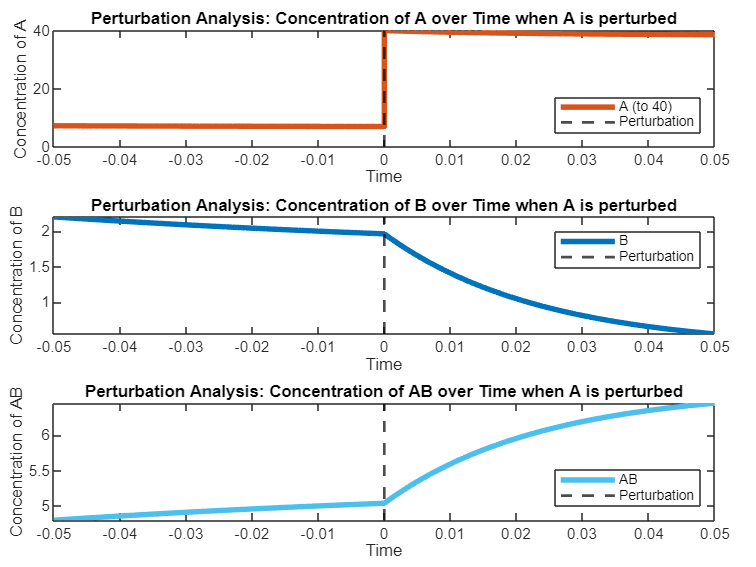


% Plot (3 stacked panels)
figure;
tiledlayout(3,1,'TileSpacing','compact','Padding','compact');

names = {'A (to 40)','B','AB'};
titles = { ...
    'Perturbation Analysis: Concentration of A over Time when A is perturbed', ...
    'Perturbation Analysis: Concentration of B over Time when A is perturbed', ...
    'Perturbation Analysis: Concentration of AB over Time when A is perturbed'};

for k = 1:3
    nexttile;
    plot(t_all, y_all(:,k), 'LineWidth', 3, 'Color', colors(k,:));
    hold on;
    xline(0,'k--','LineWidth',1.5);
    hold off;

    xlim([-cap cap]);
    xticks(-cap:0.01:cap);
    xlabel('Time');
    ylabel(['Concentration of ' strrep(names{k},' (to 40)','')]);
    title(titles{k});

    if k==1
        legend(names{k}, 'Perturbation', 'Location','southeast');
    elseif k==2
        legend(names{k}, 'Perturbation', 'Location','northeast');
    else
        legend(names{k}, 'Perturbation', 'Location','southeast');
    end
    box on;
end

When B is perturbed:

cap = 0.05;
ncap = round(cap/dt);
idx0 = round(t_perb/dt) + 1;

tpre  = (-cap:dt:0)';
tpost = (0:dt:cap)';

sol_pre = sol(idx0-ncap:idx0, :);

% Post-perturb initial condition: set B=10, keep A and AB from baseline
x0_post = [sol(idx0,1); 10.0; sol(idx0,3)];

[~, sol_post] = ode15s(@(tt,x) model_complex_formation(tt, x, params), tpost, x0_post, opts);

t_all = [tpre; tpost(1:end)];
y_all = [sol_pre; sol_post(1:end,:)];

Plot 2 (When B is perturbed): 

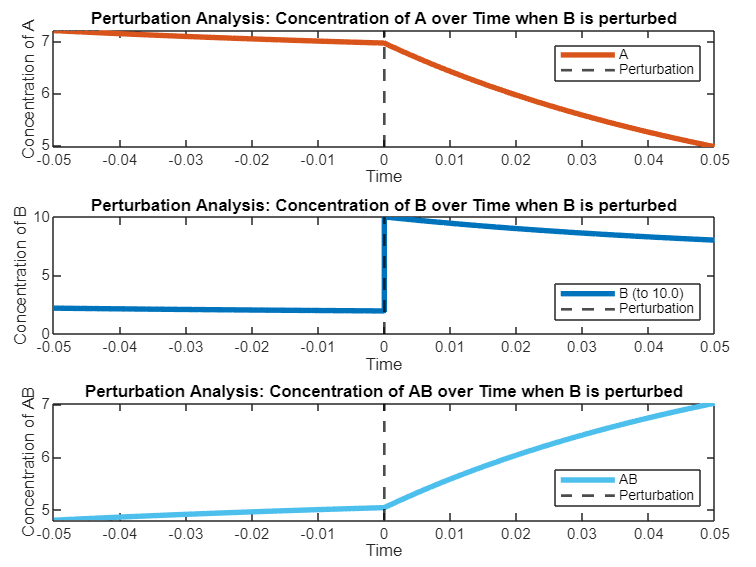

figure;
tiledlayout(3,1,'TileSpacing','compact','Padding','compact');

names = {'A','B (to 10.0)','AB'};
titles = { ...
    'Perturbation Analysis: Concentration of A over Time when B is perturbed', ...
    'Perturbation Analysis: Concentration of B over Time when B is perturbed', ...
    'Perturbation Analysis: Concentration of AB over Time when B is perturbed'};

for k = 1:3
    nexttile;
    plot(t_all, y_all(:,k), 'LineWidth', 3, 'Color', colors(k,:));
    hold on;
    xline(0,'k--','LineWidth',1.5);
    hold off;

    xlim([-cap cap]);
    xticks(-cap:0.01:cap);
    xlabel('Time');
    ylabel(['Concentration of ' strrep(names{k},' (to 10.0)','')]);
    title(titles{k});

    if k==1
        legend(names{k}, 'Perturbation', 'Location','northeast');
    elseif k==2
        legend(names{k}, 'Perturbation', 'Location','southeast');
    else
        legend(names{k}, 'Perturbation', 'Location','southeast');
    end
    box on;
end

## Export *.mlx to *.md / *.pdf

path = export("MATLAB/model_2_complex_formation.mlx", "MATLAB/model_2_complex_formation.pdf")

path = 'MATLAB\model_2_complex_formation.pdf'

mdfile = export("MATLAB/model_2_complex_formation.mlx","MATLAB/model_2_complex_formation.md", Format="markdown", EmbedImages=true, ...
    AcceptHTML=true)

mdfile = 'MATLAB\model_2_complex_formation.md'